# MPO 634 - Assignment 02 Spring 2020              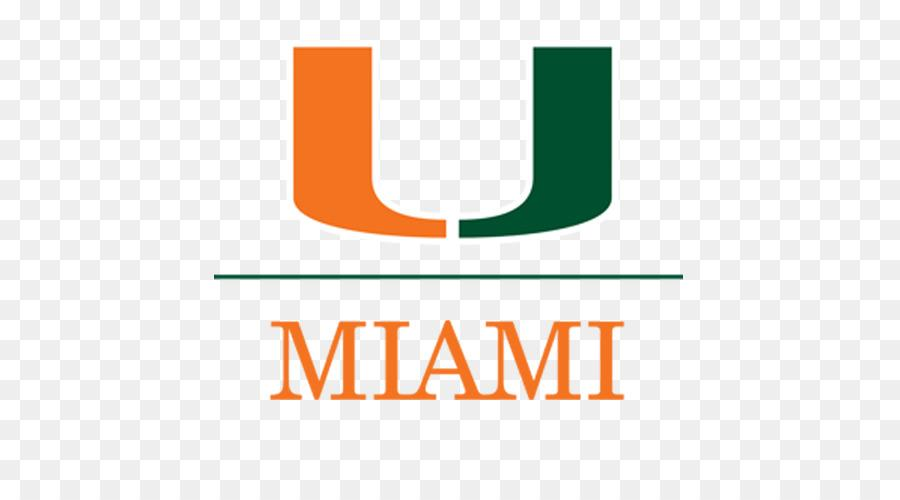

## Ivenis Pita

#### Ivenis, might you be able to use the Matlab code of problem eda06_02.m in the supplemental code .zip file at [this site](https://www.ldeo.columbia.edu/users/menke/edawm/) to do the above exercise: fitting your data as a mean, seasonal cycle, and trend without any need for gap filling.

**d** = **G** **m** + residual

**d'd** = **d'G** **m**

**m** = **(d'G)\(d'd)** in Matlab's clever notation for left-multiplying by an inverse.

clear variables
close all

stn=50250;%Station ID

%% reading data
load(['/MATLAB Drive/Data_Analysis/Assignment_02/mat_' num2str(stn) '.mat']);clear title

eval(['time=mat_' num2str(stn) '(:,1);'])
eval(['elev=mat_' num2str(stn) '(:,2);'])
clear mat_*

%% organizing time
time=time - 1721058.5;%datenum format
ind_t=time>=datenum([2002 9 18 0 0 0]);%selecting data from Sep/2002 to Aug/2004
time=time(ind_t);
elev=elev(ind_t);
clear ind_t

time=datestr(time,'dd-mm-yyyy HH');
time=datenum(time,'dd-mm-yyyy HH');
t=min(time):1/24:max(time);
t=datestr(t,'dd-mm-yyyy HH');
t=datenum(t,'dd-mm-yyyy HH');
d=nan(size(t));
[ind1,loc1]=ismember(time,t);
[ind2,loc2]=ismember(t,time);
d(ind2)=elev(ind1);
d=d-nanmean(d);

%harmonical Analysis
[tide_struc,xout]=t_tide(d,'interval',1,'start_time',t(1));

   number of standard constituents used: 68
   Points used: 16935 of 16935
   percent of var residual after lsqfit/var original: 25.04 %
   Greenwich phase computed, no nodal corrections
   Using nonlinear bootstrapped error estimates
   Generating prediction without nodal corrections, SNR is 2.000000
   percent of var residual after synthesis/var original: 26.12 %
-----------------------------------
date: 31-Mar-2020
nobs = 16935,  ngood = 16935,  record length (days) = 705.62
start time: 18-Sep-2002
rayleigh criterion = 1.0
Greenwich phase computed, no nodal corrections

x0= -0.00203, x trend= 0

var(x)= 0.16306   var(xp)= 0.12057   var(xres)= 0.042595
percent var predicted/var original= 73.9 %

     tidal amplitude and phase with 95% CI estimates

tide   freq       amp     amp_err    pha    pha_err     snr
*SA   0.0001141    0.0537    0.038   113.85    45.27        2
 SSA  0.0002282    0.0257    0.033    85.72    96.55     0.61
 MSM  0.0013098    0.0091    0.026   189.09   178.38   

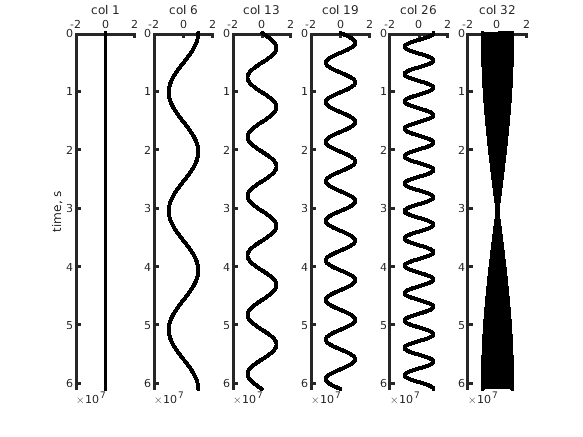

d=d-xout;

%Deliberating add NaN into my timeseries

%d(10000:11000)=nan;

%Setting matrix length
M=32;%number of frequencies I'd decompose my data
N=length(d);

tt=t; 
clear t

% set up time
Dt=60*60;% [s]
tmin=0.0;
tmax = tmin+Dt*(N-1);
t = tmin + Dt*[0:N-1]';

% nyquist frequencies
%Nf=(Dt)/2;
Nf=N/2+1;
fmax = 1/(2*Dt);
Df = fmax/(N/2);
f = Df*[0:Nf-1]';
Nw=Nf;
wmax = 2*pi*fmax;
Dw = wmax/(N/2);
w = Dw*[0:Nw-1]';

% set up G
G=zeros(N,M);

% zero frequency column
G(:,1)=nanmean(d);

% interior M/2-1 columns
for i = [1:M/2-1]
    j = 2*i;
    k = j+1;
    G(:,j)=cos(w(i+1).*t);
    G(:,k)=sin(w(i+1).*t);
end

% nyquist column
G(:,M)=cos(w(end).*t);
%G(:,M)=cos(w(Nw).*t);


% plot spectral density
figure(1)
clf;

% plot columns of G vs time
j=1;
for i = [1 round([M/5:M/5:M])]
    subplot(1,6,j);
    j=j+1;
    set(gca,'LineWidth',2);
    hold on;
    set(gca,'XAxisLocation','top');
    axis( [-2, 2, tmin, tmax] );
    axis ij;
    plot( G(:,i), t, 'k-','LineWidth',2);
    plot( G(:,i), t, 'k.','LineWidth',2);
    xlabel(sprintf('col %d',i));
    if (i==1) 
    ylabel('time, s');    
    end
end

## Calculating m and the residual

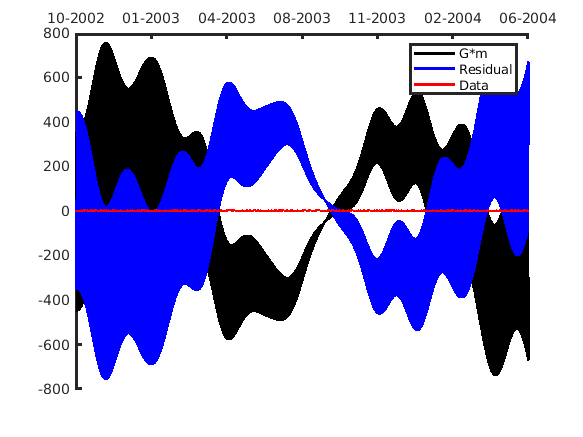

m=nan(size(G,2),1);
for j=1:size(G,2)
    m(j) = (d'*G(:,j))\(d'*d);
end

residual=d-G*m;

%% Plot the data, predicted and residual
figure
clf
set(gca,'LineWidth',2);
hold on;
set(gca,'XAxisLocation','top');
xlim( [tt(1) tt(end)] );
plot(tt,G*m,'k-','linewidth',2)
hold on
plot(tt,residual,'b-','linewidth',2)
plot(tt,d,'r-','linewidth',2)
datetick('x','mm-yyyy','keepticks')
legend('G*m','Residual','Data')

## Spectral Analysis

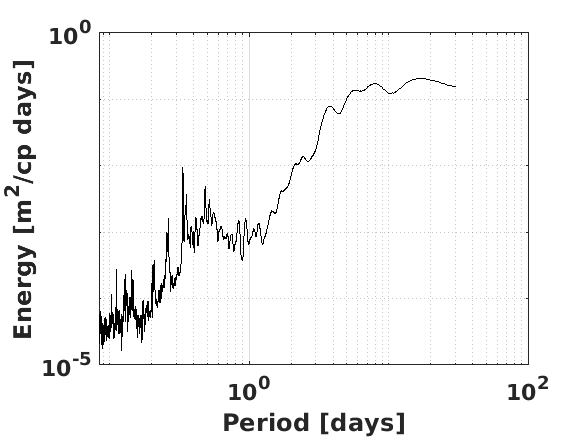

win =1; %Hanning window
ci  =95; %Confidence interval 95%
smo =2*24; %no smoothing

[h0,f,c]=specs(d,length(d),1/24,win,smo,ci);
sc       =1-(ci/100);
chi1     =c(:,3);
clo1     =c(:,4);
med      =c(:,5);
T        =1./f; %Period

figure %plot spectral analysis
%loglog(f,abs(h0),'k'), hold on
loglog((1./f),abs(h0),'k'), hold on
%line([.25 .25], [clo1(1)+5 chi1(1)+5],'color', 'r', 'Linewidth',4)
ylabel('Energy [m^2/cp days]')
%xlabel('Frequency [c/days]')
xlabel('Period [days]')
grid on
set(gca,'FontName','Helvetica','FontSize',16,'FontWeight','Bold')

## Creating a new G matrix with specific frequencies

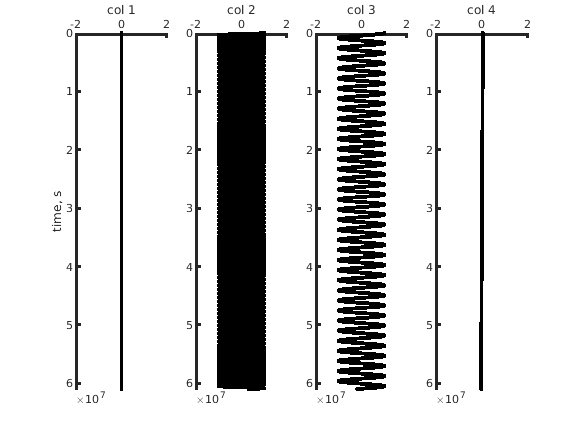

M=3;%number of frequencies I'd decompose my data

%T_specific=[0.25, 0.35,0.5,1,4,8,15];%days
T_specific=[8,20];%days
T_specific=T_specific.*(24*60*60);
f_specific=(1./T_specific);%[Hz]

% % nyquist frequencies
% %Nf=(Dt)/2;
% Nf=N/2+1;
% fmax = 1/(2*Dt);
% Df = fmax/(N/2);
% f = Df*[0:Nf-1]';
% Nw=Nf;
% wmax = 2*pi*fmax;
% Dw = wmax/(N/2);
% w = Dw*[0:Nw-1]';


% set up G
G1=zeros(N,M);

% zero frequency column
G1(:,1)=nanmean(d);

%% interior M/2-1 columns
% for i = [1:M/2]
%     j = 2*i;
%     k = j+1;
%     G1(:,j)=cos(2*pi.*f_specific(i).*t);
%     G1(:,k)=sin(2*pi.*f_specific(i).*t);
% end
% interior M/2-1 columns
for i = [2:M]
    G1(:,i)=cos(2*pi.*f_specific(i-1).*t);
end

%Calculating trend
G1(:,4)=d-detrend(d);

% plot spectral density
figure(1)
clf;

% plot columns of G vs time
j=1;
for i = 1:4

    subplot(1,4,i)
    set(gca,'LineWidth',2);
    hold on;
    set(gca,'XAxisLocation','top');
    axis( [-2, 2, tmin, tmax] );
    axis ij;
    plot( G1(:,i), t, 'k-','LineWidth',2);
    plot( G1(:,i), t, 'k.','LineWidth',2);
    xlabel(sprintf('col %d',i));
    if (i==1) 
    ylabel('time, s');    
    end
end

## Calculating m and the residual

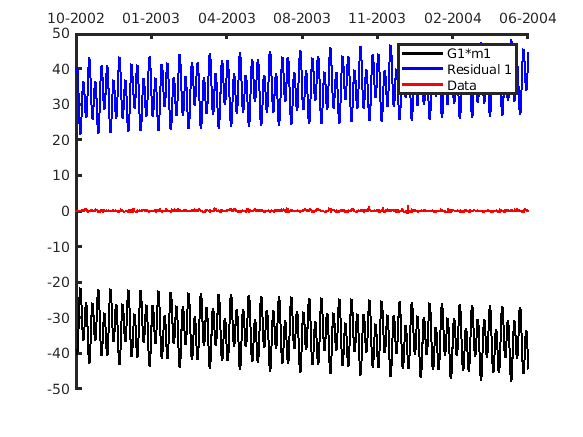

m1=nan(size(G1,2),1);
for j=1:size(G1,2)
    m1(j) = (d'*G1(:,j))\(d'*d);
end

residual1=d-G1*m1;

%% Plot the data, predicted and residual
figure
clf
set(gca,'LineWidth',2);
hold on;
set(gca,'XAxisLocation','top');
xlim( [tt(1) tt(end)] );
plot(tt,G1*m1,'k-','linewidth',2)
hold on
plot(tt,residual1,'b-','linewidth',2)
plot(tt,d,'r-','linewidth',2)
datetick('x','mm-yyyy','keepticks')
legend('G1*m1','Residual 1','Data')